clear;

load ecg_signal.txt
load ecg_noisy_1.txt
load ecg_noisy_2.txt
cs=ecg_signal;
ns1=ecg_noisy_1;
ns2=ecg_noisy_2;

level=3;
thold=0.4;

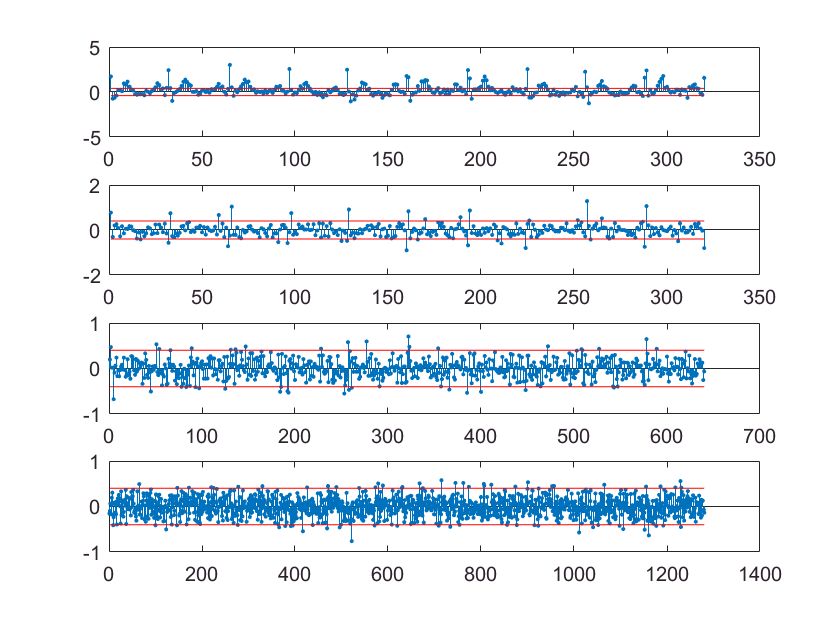

Current plot held
Current plot held
Current plot held
Current plot held


% Haar Transform
figure;
% CA=ns1;
% HTrans=cell(level+1,1);
% for i=1:level+1
%     [CA,CD]=dwt(CA,'db1');
%     HTrans{level-i+2}=CD;
% end
% HTrans{1}=CA;
HTrans=HaarTrans(ns1,level);
for i=1:level+1
    subplot(level+1,1,i)
    stem(HTrans{i},'.');
    hold;plot([1,length(HTrans{i})],[thold,thold],'r');plot([1,length(HTrans{i})],[-thold,-thold],'r');
end

% noise reduction(hard thresholding)
for i=2:level+1
    for n=1:length(HTrans{i})
        if abs(HTrans{i}(n))<thold
            HTrans{i}(n)=0;
        end
    end
end
% figure;
% for i=1:level+1
%     subplot(level+1,1,i)
%     stem(HTrans{i},'.');
%     hold;plot([1,length(HTrans{i})],[thold,thold],'r');plot([1,length(HTrans{i})],[-thold,-thold],'r');
% end
% so=HTrans{1};
% for i=2:level+1
%     so=idwt(so,HTrans{i},'db1');
% end
soHT=invHaarTrans(HTrans);

% soft thresholding
for i=2:level+1
    for n=1:length(HTrans{i})
        if abs(HTrans{i}(n))<thold
            HTrans{i}(n)=0;
        elseif HTrans{i}(n)>thold
            HTrans{i}(n)=HTrans{i}(n)-thold;
        else
            HTrans{i}(n)=HTrans{i}(n)+thold;
        end
    end
end

% x=HTrans{i}
% plot(x,min(x+thold,0)+max(x-thold,0))

soST=invHaarTrans(HTrans);

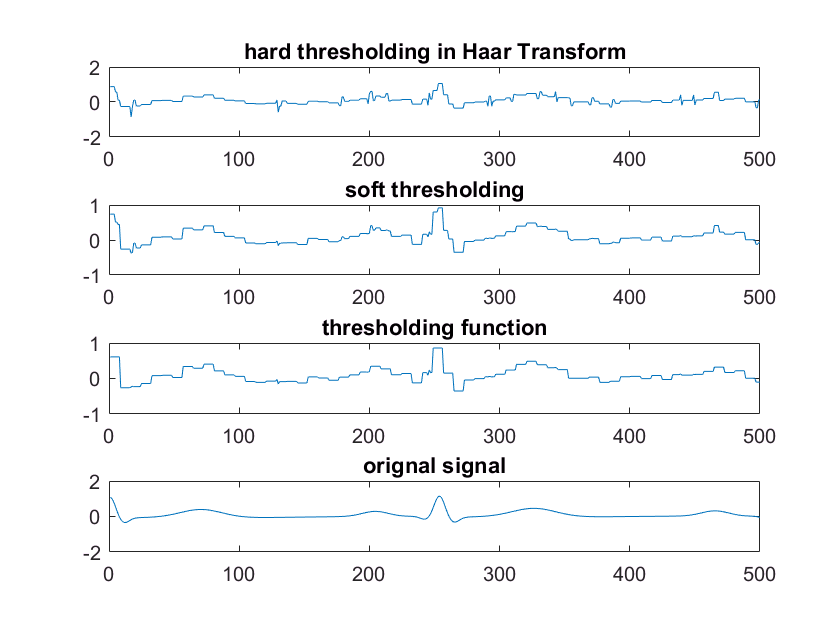

% design thresholding function
for i=2:level
    HTrans{i}=Thresholding(HTrans{i},thold);
end

soF=invHaarTrans(HTrans);

figure;
subplot(4,1,1)
% plot(soHT);title('hard thresholding in Haar Transform')
plot(soHT(1:500));title('hard thresholding in Haar Transform')
subplot(4,1,2)
% plot(soST);title('soft thresholding')
plot(soST(1:500));title('soft thresholding')
subplot(4,1,3)
% plot(soF);title('thresholding function')
plot(soF(1:500));title('thresholding function')
subplot(4,1,4)
% plot(cs);title('orignal signal')
plot(cs(1:500));title('orignal signal')

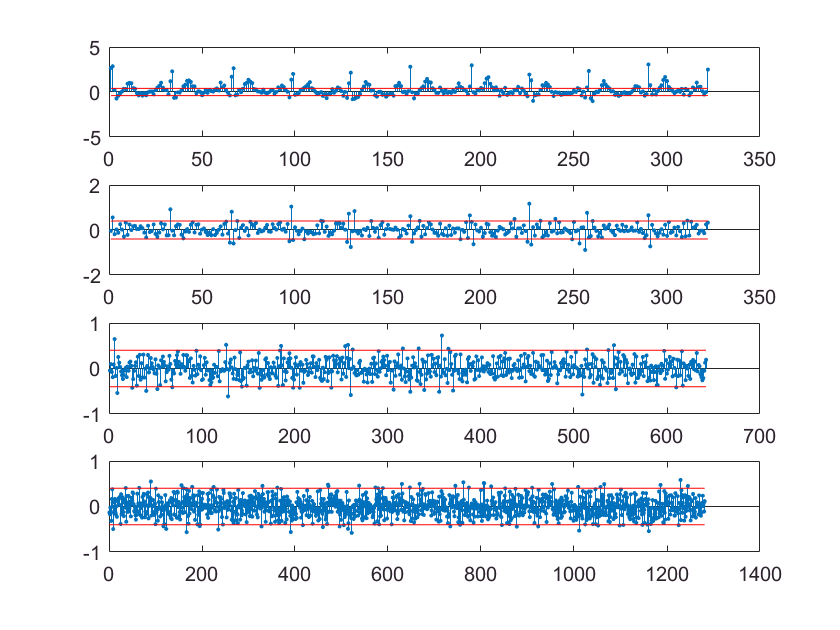

Current plot held
Current plot held
Current plot held
Current plot held


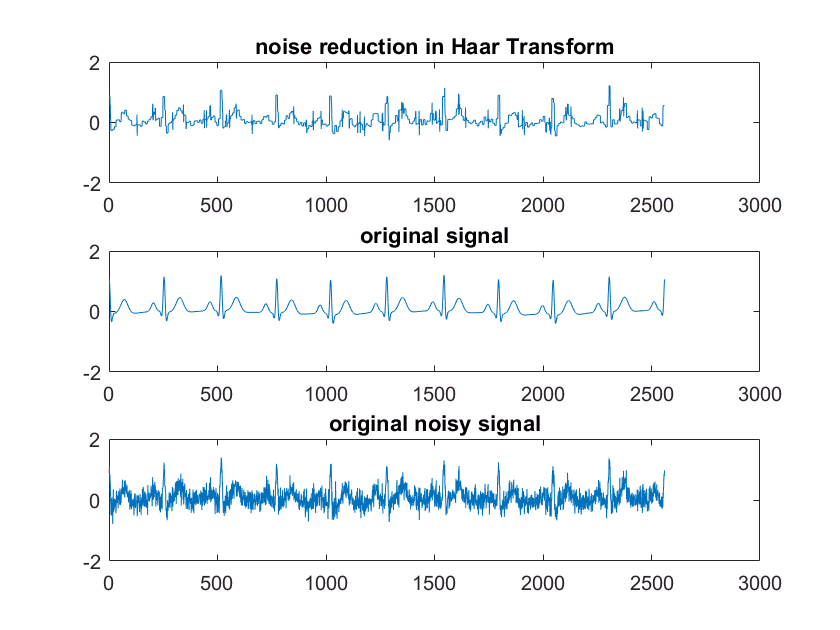

% Daubechies Transform
figure;
% CA=ns1;
% DTrans=cell(level+1,1);
% for i=1:level
%     [CA,CD]=dwt(CA,'db2');
%     DTrans{level-i+2}=CD;
% end
% DTrans{1}=CA;
DTrans=DaubechiesTrans(ns1,level);
for i=1:level+1
    subplot(level+1,1,i)
    stem(DTrans{i},'.');
    hold;plot([1,length(DTrans{i})],[thold,thold],'r');plot([1,length(DTrans{i})],[-thold,-thold],'r');
end

%   Daubechies
for i=2:level+1
    for n=1:length(DTrans{i})
        if DTrans{i}(n)<thold
            DTrans{i}(n)=0;
        end
    end
end
% figure;
% for i=1:level+1
%     subplot(level+1,1,i)
%     stem(DTrans{i},'.');
%     hold;plot([1,length(DTrans{i})],[thold,thold],'r');plot([1,length(DTrans{i})],[-thold,-thold],'r');
% end
% figure;
% so=DTrans{1};
% for i=2:level+1
%     so=idwt(so,DTrans{i},'db2');
% end

Matrix dimensions must agree.

Error in idwt (line 76)
x = upsconv1(a,Lo_R,lx,dwtEXTM,shift) + upsconv1(d,Hi_R,lx,dwtEXTM,shift);


soDT=invDaubechiesTrans(DTrans);